1. **[Overflow Error] **Matlab returns **Inf** when an overflow error in double precision is encountered. Write a script that starts with *n* = 1, calculates *n*! and increases *n* until overflow occurs (number is too big that Matlab can’t handle it). Display the value of *n* that represents the largest factorial that Matlab can handle.

%n = 0
%ans1 = 0
%while isinf(ans1) == 0
%    ans1 = factorial(n)
%    n = n + 1
%end
%disp(n)

**2. [Rounding Error]** Approximate the sequence {*π^n*} for *n* = 1 to 18 by rounding π to 1, 2, 4, and 8 decimal places. Calculate the absolute error for each sequence approximation from the sequence that uses *π *with double precision. Plot the errors for each approximate sequence on the same plot with y-axis between 0 and 5. See if you can figure out how to embed smaller plots within the main plot that zoom in on each of the sequences.

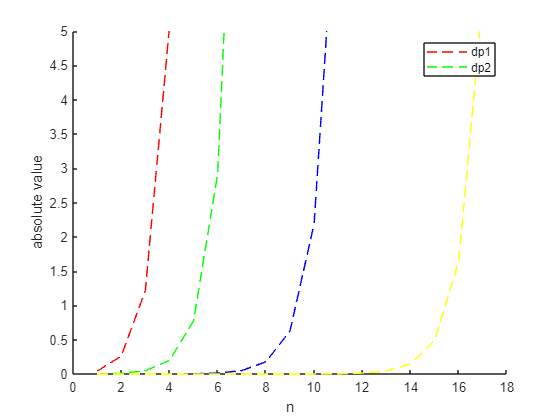

absoArr = {};
i = 1;
while i <= 8
    abso = [];
    esti = [];
    realvalue = [];
    roundpi = round(pi, i);
    for n = 1:18
        esti(end + 1) = roundpi ^ n;
        realvalue(end + 1) = pi ^ n;
        abso(end + 1) = abs(realvalue(n) - esti(n));
    end
    absoArr{end + 1} = abso;
    i = i * 2;
    x = 1:18;
end
abso1 = absoArr{1};
abso2 = absoArr{2};
abso3 = absoArr{3};
abso4 = absoArr{4};
hold on
line1 = plot(x, abso1, "r--"); label1 = "dp1";
line2 = plot(x, abso2, "g--"); label2 = "dp2";
plot(x, abso3, "b--")
plot(x, abso4, "y--")
ylim([0,5])
xlabel("n")
ylabel("absolute value")
legend([line1, line2], [label1, label2])
hold off

**3. [Truncation Error]** The Maclaurin series for cos(*x*) is cos(x) = sum_{n=0}^{inf} (-1)^n (x^(2n)) / ( 2n)! Plot the cosine function in a thick black line between –2π and 2π. On the same graph plot the Maclaurin series approximation for *n* equal to 2, 4, 8 and 16.

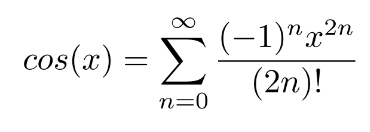

n = 2;
approx = {};
x = linspace(-2*pi, 2*pi, 100);
plot(x, cos(x), "k", 'LineWidth',2)

while n <= 16
    approx_term = 0;
    for k = 0:n
        approx_term = approx_term + ((-1)^k * (x.^(2 * k))) / factorial(2 * k);
    end
    approx{end + 1} = approx_term;
    n = n * 2;
end

hold on
n1 = plot(x, approx{1}); label1 = "n = 2"

label1 = "n = 2"

n2 = plot(x, approx{2}); label2 = "n = 4"

label2 = "n = 4"

n3 = plot(x, approx{3}); label3 = "n = 8"

label3 = "n = 8"

n4 = plot(x, approx{4}); label4 = "n = 16"

label4 = "n = 16"

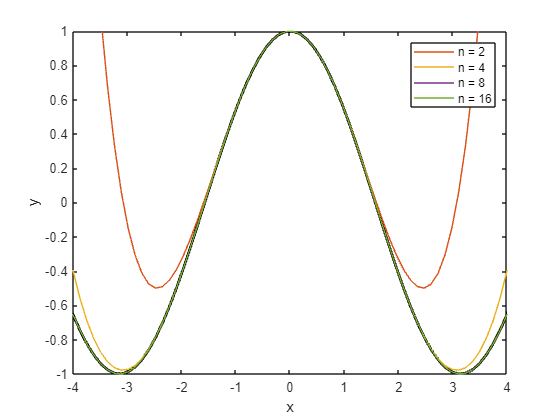

legend([n1, n2, n3, n4], [label1, label2, label3, label4])

hold off

xlabel('x');
ylabel('y');

xlim([-4, 4])
ylim([-1, 1])

**4. [Correcting Measurement Data]** Import the data from the file **data_pp4_q4.xls** using the import wizard (or using the **xlsread** command) then plot the Data against Time. The data should be corrected so that all values above 100 are normalised to exactly 100, and all values below –100 are normalised to exactly –100. Plot the corrected data on a subplot below the original.

**5. [True vs. Relative Error]** The Maclaurin series for *ex* is 

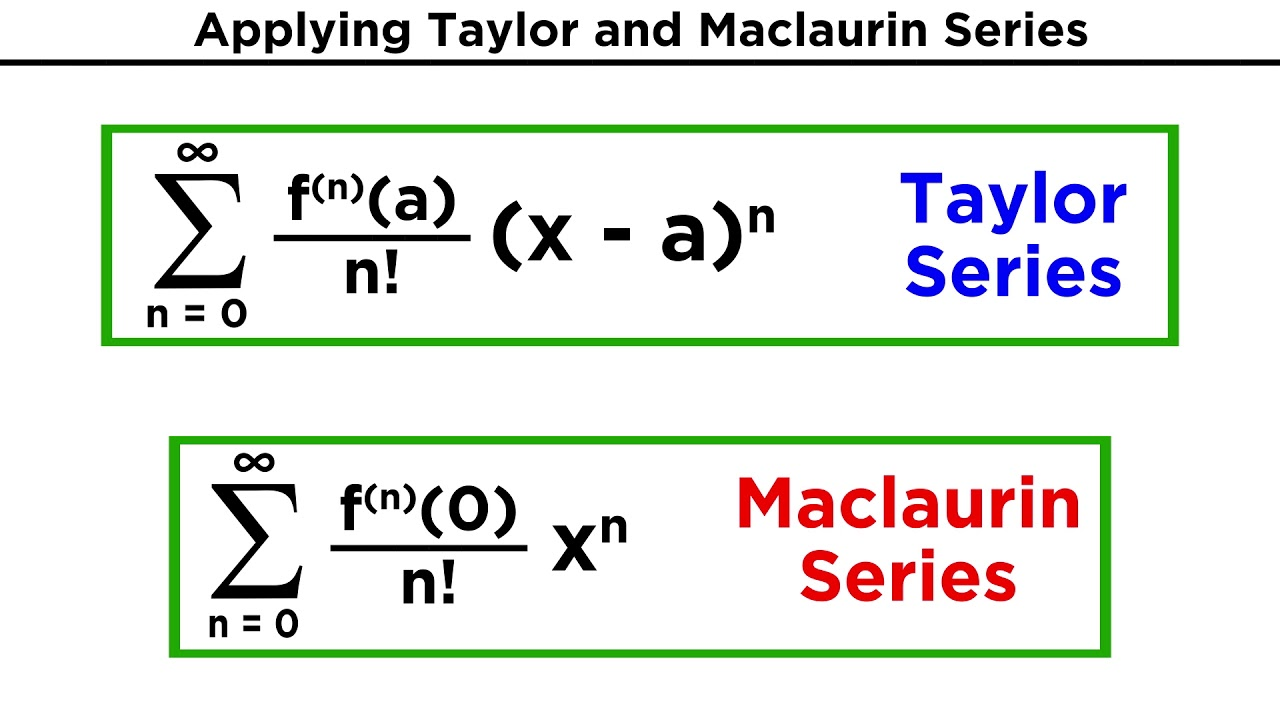

 

Plot the true function from 0 to 5 then on the same graph plot the Maclaurin approximations for *n* equal to 1, 2, 4, 8, and 16. Calculate the true absolute and true relative errors then plot these together in a separate graph.

% e^x = sum_(n=0)^inf ((x^n) / factorial(n)
% exp(1) = e
% Relative error = absolute error / measured value
% absolute error = correct value - measured value

x = linspace(0, 5, 100)

x =          0    0.0505    0.1010    0.1515    0.2020    0.2525    0.3030    0.3535    0.4040    0.4545    0.5051    0.5556    0.6061    0.6566    0.7071    0.7576    0.8081    0.8586    0.9091    0.9596    1.0101    1.0606    1.1111    1.1616    1.2121    1.2626    1.3131    1.3636    1.4141    1.4646    1.5152    1.5657    1.6162    1.6667    1.7172    1.7677    1.8182    1.8687    1.9192    1.9697    2.0202    2.0707    2.1212    2.1717    2.2222    2.2727    2.3232    2.3737    2.4242    2.4747


trueFunction = exp(x) % = e^x 

trueFunction =     1.0000    1.0518    1.1063    1.1636    1.2239    1.2873    1.3540    1.4241    1.4979    1.5755    1.6571    1.7429    1.8332    1.9282    2.0280    2.1331    2.2436    2.3598    2.4821    2.6106    2.7459    2.8881    3.0377    3.1951    3.3606    3.5347    3.7178    3.9104    4.1130    4.3260    4.5501    4.7858    5.0337    5.2945    5.5688    5.8572    6.1606    6.4798    6.8154    7.1685    7.5398    7.9304    8.3412    8.7733    9.2278    9.7058   10.2086   10.7374   11.2937   11.8787


e_curve = plot(x, trueFunction, "k", 'LineWidth', 3); labele = "true"

labele = "true"

approx = {}


approx =

  0×0 empty cell array



absoluteError = {}


absoluteError =

  0×0 empty cell array



relativeError = {}


relativeError =

  0×0 empty cell array




n = [1, 2, 4, 8, 16]

n =      1     2     4     8    16


for j = 1 : length(n)
    approx_term = 0
    for k = 0 : n(j)
        approx_term = approx_term + (x.^k) ./ factorial(k);
    end
    approx{j} = approx_term;
end

approx_term = 0

approx_term = 0

approx_term = 0

approx_term = 0

approx_term = 0


hold on
n1 = plot(x, approx{1}); label1 = "n = 1"

label1 = "n = 1"

n2 = plot(x, approx{2}); label2 = "n = 2"

label2 = "n = 2"

n3 = plot(x, approx{3}); label3 = "n = 4"

label3 = "n = 4"

n4 = plot(x, approx{4}); label4 = "n = 8"

label4 = "n = 8"

n5 = plot(x, approx{5}); label5 = "n = 16"

label5 = "n = 16"

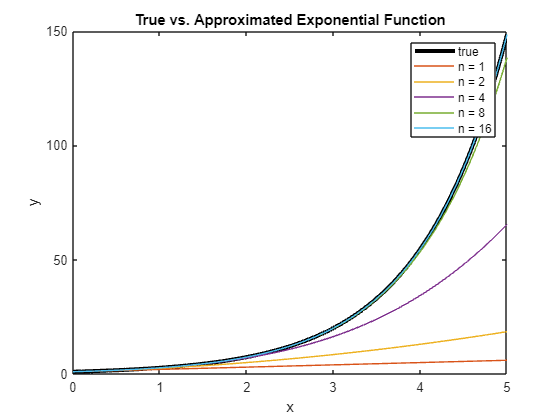

hold off

legend([e_curve, n1, n2, n3, n4, n5], [labele, label1, label2, label3, label4, label5])
xlabel("x"); % Add x-axis label
ylabel("y"); % Add y-axis label
title("True vs. Approximated Exponential Function"); % Add title


for j = 1 : length(n)
    absoluteError{j} = trueFunction - approx{j};
    relativeError{j} = absoluteError{j} ./ trueFunction;
end


figure;

n1 = plot(x, absoluteError{1}); label1 = "n = 1"

label1 = "n = 1"

hold on
n2 = plot(x, absoluteError{2}); label2 = "n = 2"

label2 = "n = 2"

n3 = plot(x, absoluteError{3}); label3 = "n = 4"

label3 = "n = 4"

n4 = plot(x, absoluteError{4}); label4 = "n = 8"

label4 = "n = 8"

n5 = plot(x, absoluteError{5}); label5 = "n = 16"

label5 = "n = 16"

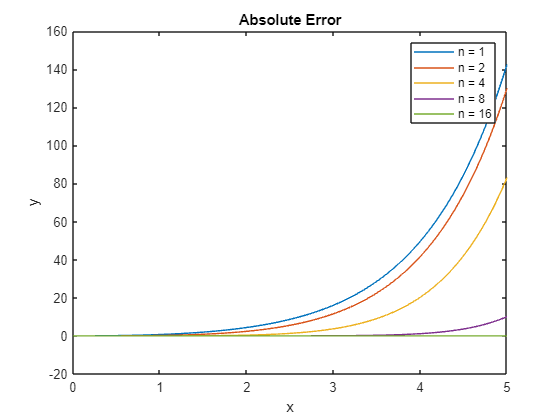


legend([n1, n2, n3, n4, n5], [label1, label2, label3, label4, label5])

hold off 

xlabel("x"); % Add x-axis label
ylabel("y"); % Add y-axis label
title("Absolute Error"); % Add title

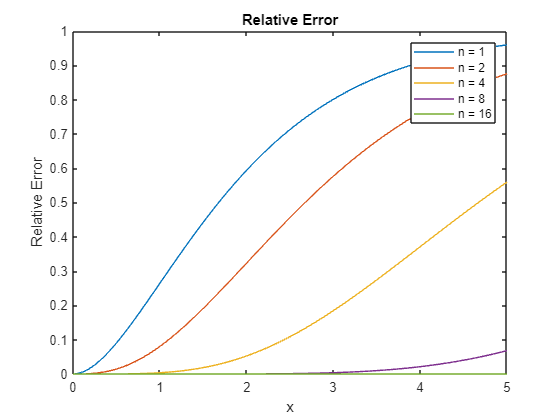


figure; 
figure;

nn1 = plot(x, relativeError{1}); label1 = "n = 1";
hold on
nn2 = plot(x, relativeError{2}); label2 = "n = 2";
nn3 = plot(x, relativeError{3}); label3 = "n = 4";
nn4 = plot(x, relativeError{4}); label4 = "n = 8";
nn5 = plot(x, relativeError{5}); label5 = "n = 16";

xlabel("x"); % Add x-axis label
ylabel("Relative Error"); % Add y-axis label
title("Relative Error"); % Add title

legend([nn1, nn2, nn3, nn4, nn5], [label1, label2, label3, label4, label5]);
hold off; % Add this line to finish the plotting

**6. [Convergence with Absolute Error Criterion]** The series is convergent. 

Write a script that finds the value the series converges to by using a loop and the absolute approximate error with a tolerance of 0.0001 (stopping criterion).

% When the limit of a series approaches a real number (i.e., the limit exists), it displays convergent behavior
% sum_ {n=0}^{inf} (4^n + 1)/factorial(3n + 1)
% Absolute Approximate Error (Ea ) = Present Approximation – Previous Approximation

approxError = inf

approxError = Inf

n = 0

n = 0

previous = 0

previous = 0


while approxError >= 0.0001 
    current = previous + ((4^n + 1) / factorial(3*n + 1))
    approxError = abs(current - previous)
    previous = current
    n = n + 1
end

current = 2

approxError = 2

previous = 2

n = 1

current = 2.2083

approxError = 0.2083

previous = 2.2083

n = 2

current = 2.2117

approxError = 0.0034

previous = 2.2117

n = 3

current = 2.2117

approxError = 1.7912e-05

previous = 2.2117

n = 4

disp(n-1)

     3



**7. [Convergence with Relative Error Criterion] **Write a script that finds the value that the series in question 6 converges to, by using a loop and the relative approximate error with a tolerance of 0.0001 (stopping criterion). Compare the results of this question with question 6.

% relative_approximate_error = abs((sum_value - previous_sum_value) / previous_sum_value);

approxRela = inf

approxRela = Inf

n = 0

n = 0

previous = 0

previous = 0


while approxRela >= 0.0001 
    current = previous + ((4^n + 1) / factorial(3*n + 1))
    if previous ~= 0
        approxRela = abs((current - previous) / previous)
    end
    previous = current
    n = n + 1
end

current = 2

previous = 2

n = 1

current = 2.2083

approxRela = 0.1042

previous = 2.2083

n = 2

current = 2.2117

approxRela = 0.0015

previous = 2.2117

n = 3

current = 2.2117

approxRela = 8.0988e-06

previous = 2.2117

n = 4

disp(n-1)

     3



**8. [Open Method Root Finding] **Write a script that implements the Incremental Search Method, with a step size of 0.1, to approximate the 3 roots to the following equation: 

Choose a sensible initial guess for your algorithm (plotting the function might help you decide).Find a way to test how closely you approximated the roots.Can you see why this method is only good for initial bracketing?

%root_approx = x - (equation(x) * 0.1) / (equation(x + 0.1) - equation(x));
equation = @(x) x.^3 - 6*x.^2 + 10*x - 4 % define function

equation = function_handle with value:
    @(x)x.^3-6*x.^2+10*x-4


roots = []


roots =

     []



count_roots = 0

count_roots = 0


x1 = linspace(-5, 5, 100)

x1 =    -5.0000   -4.8990   -4.7980   -4.6970   -4.5960   -4.4949   -4.3939   -4.2929   -4.1919   -4.0909   -3.9899   -3.8889   -3.7879   -3.6869   -3.5859   -3.4848   -3.3838   -3.2828   -3.1818   -3.0808   -2.9798   -2.8788   -2.7778   -2.6768   -2.5758   -2.4747   -2.3737   -2.2727   -2.1717   -2.0707   -1.9697   -1.8687   -1.7677   -1.6667   -1.5657   -1.4646   -1.3636   -1.2626   -1.1616   -1.0606   -0.9596   -0.8586   -0.7576   -0.6566   -0.5556   -0.4545   -0.3535   -0.2525   -0.1515   -0.0505


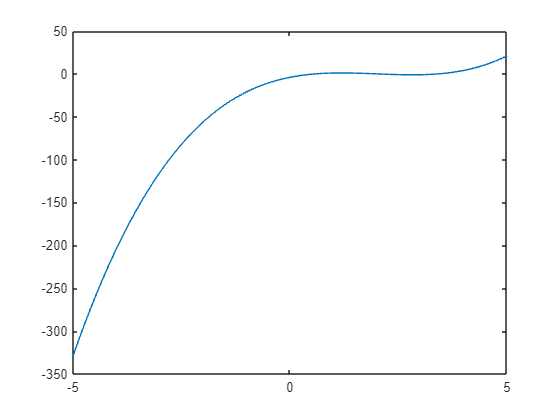

plot(x1, equation(x1))


x = -1

x = -1


while count_roots < 3
    if equation(x) * equation(x + 0.1) < 0
       root_approx = x + (x + 0.1) / 2
       roots(end + 1) = root_approx
       count_roots = count_roots + 1
    end
    x = x + 0.1
end

x = -0.9000

x = -0.8000

x = -0.7000

x = -0.6000

x = -0.5000

x = -0.4000

x = -0.3000

x = -0.2000

x = -0.1000

x = -1.3878e-16

x = 0.1000

x = 0.2000

x = 0.3000

x = 0.4000

x = 0.5000

root_approx = 0.8000

roots = 0.8000

count_roots = 1

x = 0.6000

x = 0.7000

x = 0.8000

x = 0.9000

x = 1.0000

x = 1.1000

x = 1.2000

x = 1.3000

x = 1.4000

x = 1.5000

x = 1.6000

x = 1.7000

x = 1.8000

x = 1.9000

root_approx = 2.9000

roots =     0.8000    2.9000


count_roots = 2

x = 2.0000

x = 2.1000

x = 2.2000

x = 2.3000

x = 2.4000

x = 2.5000

x = 2.6000

x = 2.7000

x = 2.8000

x = 2.9000

x = 3.0000

x = 3.1000

x = 3.2000

x = 3.3000

x = 3.4000

root_approx = 5.1500

roots =     0.8000    2.9000    5.1500


count_roots = 3

x = 3.5000

disp("approx roots : ")

approx roots : 


disp(roots)

    0.8000    2.9000    5.1500




disp("value at approximate roots")

value at approximate roots


for x = 1:length(roots)
    fprintf("For root %.6f, y = %.6f\n", roots(x), equation(roots(x)));     %.6f = float 6 decimals, %d integer
end

For root 0.800000, y = 0.672000
For root 2.900000, y = -1.071000
For root 5.150000, y = 24.955875


**9. [Preparing Open Method for Use With Closed Method] **Rewrite your script from Q9 to output 3 intervals where the roots are located between.

equation = @(x) x.^3 - 6*x.^2 + 10*x - 4 % define function

equation = function_handle with value:
    @(x)x.^3-6*x.^2+10*x-4


count_roots = 0

count_roots = 0

interval = []


interval =

     []



intervals = {}


intervals =

  0×0 empty cell array




x = -1

x = -1


while count_roots < 3
    if equation(x) * equation(x + 0.1) < 0
        interval = [x, x + 0.1]
        intervals{end + 1} = interval
        count_roots = count_roots + 1
    end
    x = x + 0.1
end

x = -0.9000

x = -0.8000

x = -0.7000

x = -0.6000

x = -0.5000

x = -0.4000

x = -0.3000

x = -0.2000

x = -0.1000

x = -1.3878e-16

x = 0.1000

x = 0.2000

x = 0.3000

x = 0.4000

x = 0.5000

interval =     0.5000    0.6000


intervals = 1×1 cell array
    {[0.5000 0.6000]}


count_roots = 1

x = 0.6000

x = 0.7000

x = 0.8000

x = 0.9000

x = 1.0000

x = 1.1000

x = 1.2000

x = 1.3000

x = 1.4000

x = 1.5000

x = 1.6000

x = 1.7000

x = 1.8000

x = 1.9000

interval =     1.9000    2.0000


intervals = 1×2 cell array
    {[0.5000 0.6000]}    {[1.9000 2.0000]}


count_roots = 2

x = 2.0000

x = 2.1000

x = 2.2000

x = 2.3000

x = 2.4000

x = 2.5000

x = 2.6000

x = 2.7000

x = 2.8000

x = 2.9000

x = 3.0000

x = 3.1000

x = 3.2000

x = 3.3000

x = 3.4000

interval =     3.4000    3.5000


intervals = 1×3 cell array
    {[0.5000 0.6000]}    {[1.9000 2.0000]}    {[3.4000 3.5000]}


count_roots = 3

x = 3.5000


disp("intervals : ")

intervals : 


disp(intervals)

    {[0.5000 0.6000]}    {[1.9000 2.0000]}    {[3.4000 3.5000]}



**10. [Generalising Method to Any Function]** Write a Matlab function file that implements the Incremental Search Method. The user should be able to input a function f(x), step size h, and range of values to search between [x0,xend]. The output should be a list of brackets (intervals) containing each root. 

Test your function with the function 

 

on the interval [3, 6] with step sizes of 0.06 and 0.03.

Q10(0.03, 3, 6)

Question10
intervals : 
    {[3.2400 3.2700]}    {[3.3600 3.3900]}    {[3.7200 3.7500]}    {[4.2000 4.2300]}    {[4.2600 4.2900]}    {[4.7100 4.7400]}    {[5.1600 5.1900]}    {[5.1900 5.2200]}    {[5.6700 5.7000]}



function Q10(h, x0, xend) 
    disp("Question10")
    equation = @(x) sin(10 * x) + cos(3 * x);
    interval = [];
    intervals = {};    
    for x = x0 : h : xend
        if equation(x) * equation(x + h) < 0
            interval = [x, x + h];
            intervals{end + 1} = interval;
        end
    end
    disp("intervals : ")
    disp(intervals)
end